# MLTWA Analysis

clear; clc; close all;

## 1. Input data

Add the original .mat file with the calculated energies for the 4 windows.

**DATA FORMAT REQUIRED:** The code expects a 5-column matrix of non-corrected energies:

- Col 1: Distances km

- Col 2: First Window energies

- Col 3: Second Window energies

- Col 4: Third Window energies

- Col 5: Coda Window energies (for normalization)

**However**, if your energies are **already corrected** for Geometrical Spreading, normalized by the coda, and in log10 scale, the code can handle this and avoid double corrections. You just need to set the data processing flag to TRUE (as explained later in the code). In this specific case, a 4-column matrix is sufficient (Col 1: Distances, Col 2-4: Processed Window energies).

**VARIABLE NAMING: **You don't necessarily need to rename the variables inside your .mat file. The script features a smart data loader: it will first look for the EXACT name you define in the 'labels' array below (e.g., if labels={'My_Freq_1_5'}, it looks for that specific variable). If the exact label isn't found, it uses the 'freqs' array to automatically guess standard MLTWA naming conventions (e.g., for 1.5 Hz, it will search for 'E1_5Hz', 'f1_5Hz', or 'Freq_1_5').

filename = 'MLTWA_Visso_corrected.mat'; 

if isfile(filename)
    raw_file = load(filename); 
    fprintf('File "%s" successfully loaded.\n', filename);
else
    error('File not found! Please check the name or path.');
end

File "MLTWA_Visso_Prova.mat" successfully loaded.


% --- Data Processing Flag ---
% Set to 'true' if your data is already normalized by coda, corrected for 
% geometrical spreading, and in log10 scale.
% Set to 'false' if your data is raw and needs this processing.

is_data_processed = false;
freqs = [1.5, 3, 6, 12];
% freqs = 1.5;

labels = {'f1_5Hz', 'f3Hz', 'f6Hz', 'f12Hz'};
% labels = {'f1_5Hz'};

data_ready = prepare_mltwa_data(raw_file, freqs, labels, is_data_processed);


--- Loading and Processing Energies ---
  -> f1_5Hz: Processed (Coda norm + Geom spread + Log10 applied).
  -> f3Hz: Processed (Coda norm + Geom spread + Log10 applied).
  -> f6Hz: Processed (Coda norm + Geom spread + Log10 applied).
  -> f12Hz: Processed (Coda norm + Geom spread + Log10 applied).


Now, add the physical parameters for the calculation, and the size of the grid where you will perform the grid-search.

% --- Physical Parameters ---
sim_params = struct();
sim_params.v = 3.5;              % S-wave velocity
sim_params.deltaT = 15;          % Time window length 
sim_params.Fs = 10;              % Sampling frequency
sim_params.t_coda = 50;          % Coda start time
sim_params.min_dist = 20;         % Minimum distance for analysis
sim_params.max_dist = 80;        % Maximum distance for analysis

% --- Parallel Computing Settings ---
% 'auto' = uses all available physical cores (maximum speed).
% 0      = disables parallelization (runs sequentially, NO toolbox required).
% N      = uses exactly N cores (e.g., set to 4 to keep your PC usable).
sim_params.num_workers = 'auto';

% --- Grid Search Settings ---
% Change here for the grid size (third variable in the linspace function.
% Here as an example is 10.
grid_settings = struct();
grid_settings.b0_vec = linspace(0.01, 0.99,20); % B0 (Seismic Albedo) grid
grid_settings.le_vec = linspace(0.005, 0.2, 20); % Le^-1 (Extinction Length) grid

## 2. Data Check and example of B0 and Le-1 

Number of outliers removed (top/bottom 0.5%)


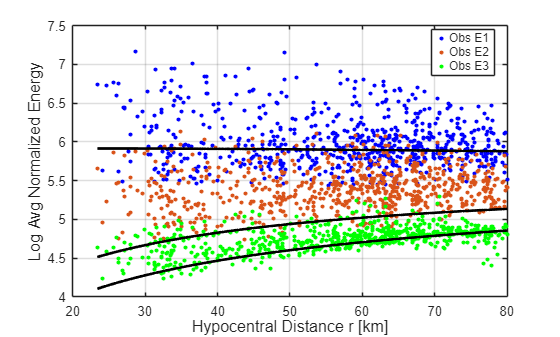

mse = 0.40099


if isfield(data_ready, 'f1_5Hz')
    d_check = data_ready.f1_5Hz;
    data_struct = struct('rn', d_check(:,1), 'E1', d_check(:,2), 'E2', d_check(:,3), 'E3', d_check(:,4));
    mse = analysis_one_point(0.7, 0.01, data_struct, sim_params);
    disp("mse = " + mse);
else
    warning('f1_5Hz data not available for check.');
end

## 3. Grid Search Run

final_results = run_MLTWA_automation(data_ready, sim_params, grid_settings, freqs, labels);

 -> Working on frequency: 1.5 Hz... (PNG 2x2 saved).
 -> Working on frequency: 3.0 Hz... (PNG 2x2 saved).
 -> Working on frequency: 6.0 Hz... (PNG 2x2 saved).
 -> Working on frequency: 12.0 Hz... (PNG 2x2 saved).
--- COMPLETED ---



save('Final_Complete_Results.mat', 'final_results');

## 4. Results

Set to 'true' to use the centroid of multiple local minima (if present).Set to 'false' to strictly use the absolute minimum of the grid.

use_centroid = false;
use_smooth   = true; 

ResultsTable = extract_mltwa_results_table(final_results, freqs, labels, sim_params.v, use_centroid,use_smooth);
disp(ResultsTable);

    Freq_Hz        Le_inv              B0                 Qt_inv                   Qi_inv                   Qs_inv        
    _______    _______________    _____________    _____________________    _____________________    _____________________

      1.5      "0.056 ± 0.005"    "0.63 ± 0.03"    "2.09e-02 ± 1.91e-03"    "7.76e-03 ± 6.95e-05"    "1.32e-02 ± 1.84e-03"
        3      "0.046 ± 0.005"    "0.47 ± 0.03"    "8.55e-03 ± 9.53e-04"    "4.50e-03 ± 2.31e-04"    "4.06e-03 ± 7.22e-04"
        6      "0.036 ± 0.005"    "0.22 ± 0.05"    "3.32e-03 ± 4.76e-04"    "2.60e-03 ± 1.53e-04"    "7.19e-04 ± 3.24e-04"
       12      "0.036 ± 0.000"    "0.11 ± 0.00"    "1.66e-03 ± 0.00e+00"    "1.47e-03 ± 0.00e+00"    "1.88e-04 ± 0.00e+00"



writetable(ResultsTable, 'Final_Table_B0_Le.txt', 'Delimiter', '\t');